# TFL Demo

## Initial MATLAB setup

addpath(genpath('src'));   % add helpers
if ~exist('figs','dir'), mkdir figs; end
if ~exist('InitBreach','file')
    error('Breach not found. Add Breach to the MATLAB path before running.');
end
InitBreach

Initializing Breach from folder C:\Users\Nackha1\Documents\UniUD\thesis\breach-master...


## Configuration

rng(128);

% Sampling
Fs   = 500;                       % Hz
T    = 1;                         % seconds per trace
M    = round(Fs*T);               % samples per trace
t    = (0:M-1)'/Fs;
fmax = 15;                        % Hz cutoff for TF plots/aggregation

% Dataset
n_traces       = 256;             % number of traces
ring_frac      = 0.05;            % fraction with injected ringing
f0_sim         = 1.25;            % ringing freq used in SIMULATION (unknown to learner)
train_ratio    = 0.8;             % 80/20 train/test split (stratified)
safe_bands     = [0.9 0.9];       % rows [fmin fmax] defining NORMAL energy bands
A_ring         = 0.15;            % ringing amplitude
dur_ring_range = [0.8 2.0];       % s
SNR_dB         = 25;              % baseline SNR for normals

% STFT (choose longer window for sub-1 Hz structure)
win_len  = round(4*Fs);
noverlap = round(0.9*win_len);
nfft     = 2^nextpow2(win_len);

% Aggregation across out-of-safe freqs
agg_mode = 'sum';

% Simulated Annealing
init_temp = 100.0;
max_iter = 16;

% % Figure saver: create figs/<yyyy-MM-dd_HHmmss>/ and reset counter
run_id  = string(datetime('now'), 'yyyy-MM-dd_HHmmss');
run_dir = fullfile('figs', run_id);
savefig_seq('init', run_dir);
fprintf('Saving figures to: %s\n', run_dir);

## Dataset

Generation

% [X, labels] = build_ringing_dataset(Fs, T, n_traces, ring_frac, f0_sim, A_ring, dur_ring_range);

[X,labels] = build_degradation_dataset(Fs, T, n_traces, ring_frac, 90, [8 16], 10);

X = add_noise(X, SNR_dB);

Plot

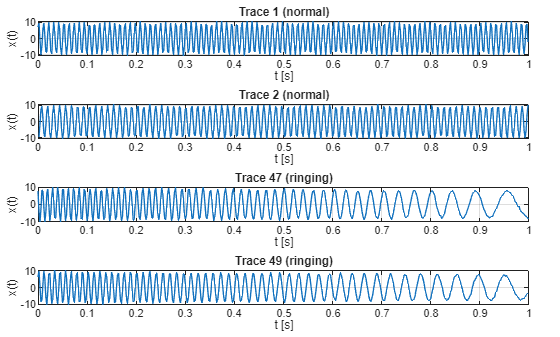

pick_norm = find(labels==0, 2, 'first');
pick_ring = find(labels==1, 2, 'first');
picks = [pick_norm(:); pick_ring(:)];
figure('Name','Sample time series');
tiledlayout(numel(picks),1,'Padding','compact','TileSpacing','compact');
for i = 1:numel(picks)
    k = picks(i);
    nexttile;
    plot(t, X(:,k));
    grid on;
    title(sprintf('Trace %d (%s)', k, tern(labels(k)==0,'normal','anomalous')));
    xlabel('t [s]'); ylabel('x(t)');
end

savefig_seq('save', gcf, 'sample_time_series');

## Frequency-Time Analysis

Computation of z_out

% Z = compute_zout_from_stft(X, Fs, win_len, noverlap, nfft, safe_bands, fmax, agg_mode);
Z = compute_zout_from_cwt(X, Fs, safe_bands, fmax, 'max_f');

Energy Plot

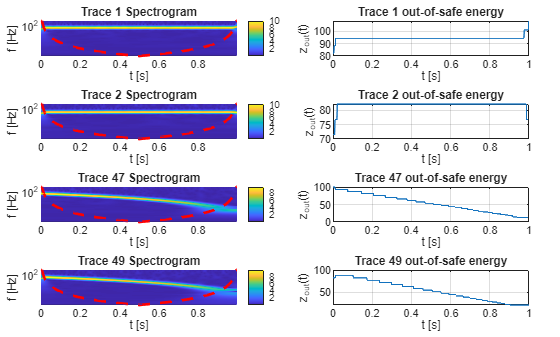

figure('Name','Spectrogram + z_{out}(t)');
tiledlayout(numel(picks),2,'Padding','compact','TileSpacing','compact');
for i = 1:numel(picks)
    k = picks(i);

    % [S,F,Tstft] = spectrogram(X(:,k), win_len, noverlap, nfft, Fs, 'yaxis');

    fb = cwtfilterbank(SignalLength=M, SamplingFrequency=Fs);
    [S,F,coi] = cwt(X(:,k), FilterBank=fb);
    
    P = abs(S);

    % keep = F <= fmax;
    % F    = F(keep);
    % P    = P(keep,:);

    nexttile;
    % imagesc(Tstft, F, 10*log10(P+eps));
    % surf(Tstft, F, P);
    surf(t, F, P);
    % contour(t,F,P);
    set(gca,'YScale','log');
    shading interp;
    view(0, 90);
    axis tight;
    colorbar;

    hold on;
    % yline(safe_bands,'w--');
    z_coi = interp2(t, F, P, t, coi, 'linear', 0);
    plot3(t, coi, z_coi, 'r--', 'LineWidth', 2);
    hold off;

    xlabel('t [s]')
    ylabel('f [Hz]');
    % title(sprintf('Trace %d STFT (dB)', k));
    title(sprintf('Trace %d Spectrogram', k));

    nexttile;
    plot(t, Z(:,k));
    grid on;
    xlabel('t [s]');
    ylabel('z_{out}(t)');
    title(sprintf('Trace %d spectral predicate', k));
end

savefig_seq('save', gcf, 'spectrogram_and_zout_examples');

## Train/Test split

[idx_train, idx_test] = split_train_test(labels, train_ratio);

ytrue_train = 1 - labels(idx_train);   % 1=normal, 0=anomalous

% Data-driven prior interval for theta from TRAIN set
th_lo = min(Z(:,idx_train), [], 'all');
th_hi = max(Z(:,idx_train), [], 'all');
theta0 = 0.5*(th_lo+th_hi);

## Breach setup

[Br, TR] = make_breach_traces(t, X, Z, {'x','zout'});

% phi_str = 'alw_[0,T] ( zout[t] <= th )';
phi_str = 'alw_[0,T] ( zout[t] >= th )';
phi     = STL_Formula('phi', phi_str);
phi     = set_params(phi, {'T'}, T);

Br_train = br_subset_from_idx(TR, {'x','zout'}, idx_train);
Br_test  = br_subset_from_idx(TR, {'x','zout'}, idx_test);

## Training phase

sa_obj  = @(theta) mcr_on_split(Br_train, phi, theta, ytrue_train);
opts_sa = optimoptions('simulannealbnd', ...
    'Display', 'iter', ...
    'InitialTemperature', init_temp, ...
    'MaxIterations', max_iter);

[theta_star, mcr_train_best, exitflag, output] = simulannealbnd(sa_obj, theta0, th_lo, th_hi, opts_sa);


                           Best        Current           Mean
Iteration   f-count         f(x)         f(x)         temperature
     0          1              0              0            100
    10         11              0              0          56.88
    16         17              0      0.0637255         41.812
simulannealbnd stopped because it exceeded the iteration limit. Increase options.MaxIterations.


fprintf('TRAIN SA: theta* = %.6g | MCR_train = %.4f | prior box = [%.6g, %.6g] | exitflag=%d, iters=%d\n', ...
    theta_star, mcr_train_best, th_lo, th_hi, exitflag, output.iterations);

TRAIN SA: theta* = 64.4893 | MCR_train = 0.0000 | prior box = [12.6579, 116.321] | exitflag=0, iters=17


## Evaluation on Test Set

Br_test.SetParamSpec('th', theta_star);
rob_test   = Br_test.CheckSpec(phi);
yhat_test  = double(rob_test>=0);       % 1=normal, 0=anomalous
ytrue_test  = 1 - labels(idx_test);     % 1=normal, 0=anomalous

C = confusionmat(ytrue_test, yhat_test);
TN = C(1,1); FP = C(1,2); FN = C(2,1); TP = C(2,2);
N  = sum(C,'all');

acc = (TP + TN) / N;
mcr = 1 - acc;
prec = TP / max(TP + FP, 1);
tpr  = TP / max(TP + FN, 1);
fpr  = FP / max(FP + TN, 1);

function print_confusion_matrix(TN,FP,FN,TP,acc,mcr,prec,tpr,fpr,N)
    fprintf('\nTEST PERFORMANCE\n');
    fprintf('                Pred 0        Pred 1\n');
    fprintf('Actual 0        %6d        %6d\n', TN, FP);
    fprintf('Actual 1        %6d        %6d\n', FN, TP);
    fprintf('acc=%.3f  mcr=%.3f  prec=%.3f  tpr=%.3f  fpr=%.3f  | n_test=%d\n\n', ...
    acc, mcr, prec, tpr, fpr, N);
end

print_confusion_matrix(TN,FP,FN,TP,acc,mcr,prec,tpr,fpr,N);


TEST PERFORMANCE
                Pred 0        Pred 1
Actual 0             4             0
Actual 1             0            48
acc=1.000  mcr=0.000  prec=1.000  tpr=1.000  fpr=0.000  | n_test=52



## Results Overview

Br_eval = Br.copy();
Br_eval.SetParamSpec('th', theta_star);
rob_total   = Br_eval.CheckSpec(phi);
yhat_total  = double(rob_total>=0);
ytrue_total = 1 - labels;

mis_idx  = find(yhat_total~=ytrue_total);
corr_idx = find(yhat_total==ytrue_total);
n_mis    = numel(mis_idx);

Classification examples

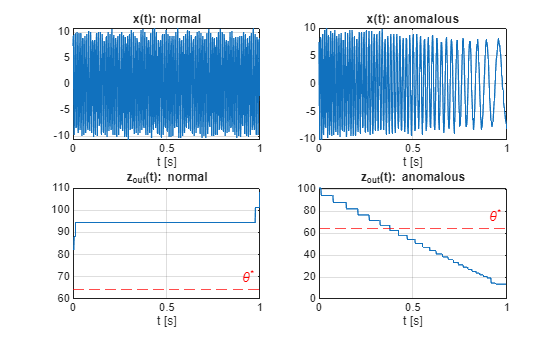

% One normal and one ringing correctly classified (if exist)
exN = find(ytrue_total==1 & yhat_total==1, 1, 'first');
exR = find(ytrue_total==0 & yhat_total==0, 1, 'first');

if ~isempty(exN) && ~isempty(exR)
    figure('Name','Example normal vs anomalous with \theta^*');
    subplot(2,2,1); plot(t, X(:,exN)); grid on; title('x(t): normal'); xlabel('t [s]');
    subplot(2,2,3); plot(t, Z(:,exN)); hold on; yline(theta_star,'r--','\theta^*'); grid on;
    title('z_{out}(t): normal'); xlabel('t [s]');
    subplot(2,2,2); plot(t, X(:,exR)); grid on; title('x(t): anomalous'); xlabel('t [s]');
    subplot(2,2,4); plot(t, Z(:,exR)); hold on; yline(theta_star,'r--','\theta^*'); grid on;
    title('z_{out}(t): anomalous'); xlabel('t [s]');
    savefig_seq('save', gcf, 'example_normal_vs_anomalous');
end

Misclassified traces

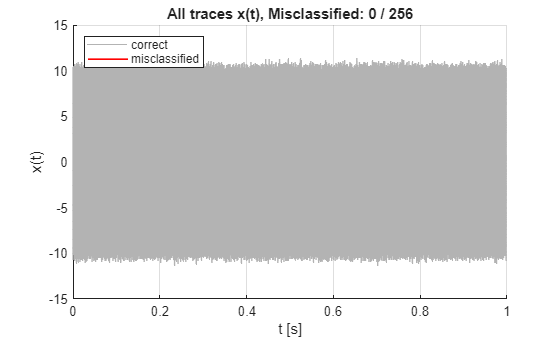

figure('Name','ALL x(t): misclassified highlighted','Color','w'); hold on; grid on;
h_corr = plot(t, X(:,corr_idx), 'Color', [0.7 0.7 0.7]);
if ~isempty(mis_idx)
    h_mis = plot(t, X(:,mis_idx), 'Color', 'r', 'LineWidth', 1.2);
else
    h_mis = plot(nan, nan, 'Color', 'r', 'LineWidth', 1.2);
end
xlabel('t [s]'); ylabel('x(t)');
title(sprintf('All traces x(t), Misclassified: %d / %d', n_mis, size(X,2)));
legend([h_corr(1), h_mis(1)], {'correct','misclassified'}, 'Location','northwest');

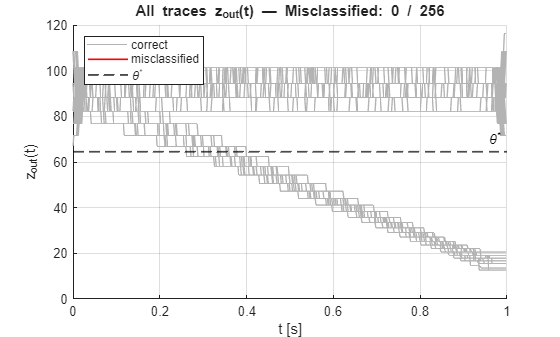

savefig_seq('save', gcf, 'all_x_misclassified');
figure('Name','ALL z_{out}(t): misclassified highlighted','Color','w'); hold on; grid on;
h_corr = plot(t, Z(:,corr_idx), 'Color', [0.7 0.7 0.7]);
if ~isempty(mis_idx)
    h_mis = plot(t, Z(:,mis_idx), 'Color', 'r', 'LineWidth', 1.2);
else
    h_mis = plot(nan, nan, 'r', 'LineWidth', 1.2);
end
h_thr = yline(theta_star, '--k', '\theta^*', 'LineWidth', 1.4);
xlabel('t [s]'); ylabel('z_{out}(t)');
title(sprintf('All traces z_{out}(t) — Misclassified: %d / %d', n_mis, size(Z,2)));

legend([h_corr(1), h_mis(1), h_thr], ...
   {'correct','misclassified','\theta^*'}, ...
   'Location','northwest');

savefig_seq('save', gcf, 'all_zout_misclassified');

Robustness per trace

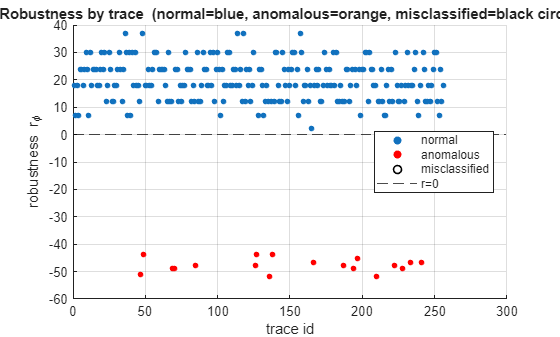

figure('Name','Robustness per trace','Color','w'); hold on; grid on;
idx_norm_all = find(ytrue_total==1);
idx_ring_all = find(ytrue_total==0);
h_norm = scatter(idx_norm_all, rob_total(idx_norm_all), 18, 'filled');
h_ring = scatter(idx_ring_all, rob_total(idx_ring_all), 18, 'r', 'filled');
if ~isempty(mis_idx)
    h_mis = scatter(mis_idx, rob_total(mis_idx), 60, 'o', ...
        'MarkerEdgeColor','k', 'LineWidth',1.2, 'MarkerFaceColor','none');
else
     h_mis = scatter(nan, nan, 60, 'o', ...
        'MarkerEdgeColor','k', 'LineWidth',1.2, 'MarkerFaceColor','none');
end
h_zero = yline(0, 'k--');
xlabel('trace id'); ylabel('robustness r_\phi');
title('Robustness by trace  (normal=blue, anomalous=orange, misclassified=black circle)');
legend([h_norm, h_ring, h_mis, h_zero], {'normal','anomalous','misclassified','r=0'}, 'Location','best');
savefig_seq('save', gcf, 'robustness_by_trace');